# PA Modeling and DPD Implementation 

This example shows to implement the PA model and apply DPD methology for correction.

#### History

- 2024-09-19, Draft

- 2024-09-26, Release V1.0, Apply PA model fitting coefs. >> inverse Matrix DPD >> CFR

- 2024-10-11, Draft V2.0, Apply MemoryDepth effect

#### Set Test Waveform

Rohm = 1 % set resistor in ohm

Rohm =      1


RbwKHz = 10 % set resolution bw for aclr plot

RbwKHz =     10


testSignal = "WIFI"; % select signal

switch upper(testSignal) % open example
    case "WIFI"
        try
            signalFormat;
        catch
            open('Example_WIFI_Transmit_240919_v1.mlx')
        end
        paInput = paInSignal;
        paOutput = paSignal;
        paOutput_org = paSignal;

    case "CW"

end


#### Plot Test Waveform

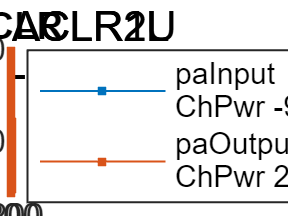

pltComm = PLOT_COMM('aclr', aclrVal_wv, [], RbwKHz, Rohm); % set plt object
aclrVal_paIn = pltComm.ACLR(paInput, {091901, 'paInput'}); % plot aclr
aclrVal_paOut = pltComm.ACLR(paOutput, {091901, 'paOutput'}); % plot aclr

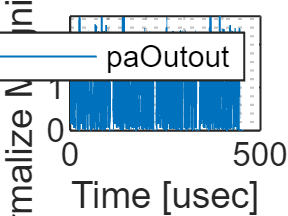

pltComm.TIME(paOutput, {092001, 'paOutout'}, [], 'usec'); % plot time

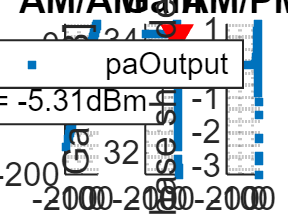

pltComm.AMAM([paInput, paOutput], {092002, 'paOutput'}, 0.01); % plot amam

#### PA Characterization - MemoryLess Polynomial Model

Create coefficients of MemoryLess Polynomial Model using PA input and ouput data.

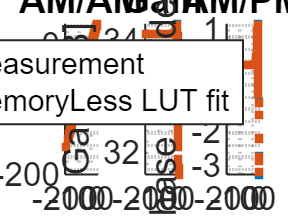

inputPowerBackOffDb = 40; % set the minimum power range using peak power back-off
[~, paMemLess_obj, paOutput_fitMemLess] = rfSim_pa_memoryLessLUTModel([paInput,paOutput],...
    inputPowerBackOffDb,Rohm,070403);

#### PA Characterization - Memory Polynomial Model

Create coefficients of Memory Polynomial Model using PA input and ouput data.

#### Sweep Polynomial Order and Memory Depth

To search the minimum rms error in %

setInputPowerRangeDbm = -70; % set the mimimun power of pa input instantaneous signal
isSweepMemoryPolynomialFit = 0;
nSamps = length(paInput); % signal length

% set signal captured length to compute the fitting coefficients
if 0
    nCapturedSamps = nSamps/2;
elseif 1*0
    nCapturedSamps = nSamps - 0;
else
    nCapturedSamps = nSamps;
end

% set fitting model using the polynminal order and memory depth
if 1 % set sweeping range
    MemoryDepth_max = 7;
    Degree_max = 11;
    Degree_step = 1;
    Degree_start = 1;
end

MemDepth_sweep = [0:MemoryDepth_max]; % start from 0
Degree_sweep = {Degree_start,Degree_step,[Degree_start:2:Degree_max]}; % start from 0

if isSweepMemoryPolynomialFit
    % sweep memory polynomial parameters
    tic
    [~,~,~,evmList] = rfSim_pa_memoryModel([paInput(1:nCapturedSamps),paOutput(1:nCapturedSamps)],...
        'coefficientFinder',Degree_sweep,MemDepth_sweep,[],[],setInputPowerRangeDbm,Rohm); hold on
    toc

    % plot contourf - evm in %
    plt_contourf(evmList, [], {Degree_sweep{end}, MemDepth_sweep},...
        {[070404,1,1,1], 'Polynomial Degree', 'Memory Depth', 'EVM. Sweep [%%] for PA output fit signal'}, 'min')
end

#### Sweep Polynomial Order, Memory Depth, Cross Delay and Cross Lag

To search the minimum rms error in %

isSweepCrossTerm = 0;

#### Create Memory Polynomial Fitting PA Output with/without Cross Terms

To evaluate the rms error of fitting results

if isSweepCrossTerm % set memory polynomial cross term parameters
    Degree_fit_set={1,2,11};
    MemoryDepth_fit_set={0,1,4};
    CrossDelay_set{3}=1;
    CrossLag_set{3}=1;
    dispLgnd_paOutput_fit = sprintf('MemoryPolynomial wi Cross Term Fit \nK=%d, M=%d, CDelay=%d, CLag=%d',...
        Degree_fit_set{end},MemoryDepth_fit_set{end},CrossDelay_set{3},CrossLag_set{3})
else % set memory polynomial without cross term parameters
    Degree_fit_set={1,Degree_step,7}; % set max. degree based on min. rmsError
    MemoryDepth_fit_set={0,1,2}; % set max. memory based on min. rmsError
    CrossDelay_set=[];
    CrossLag_set=[];
    dispLgnd_paOutput_fit = sprintf('MemoryPolynomial \nK=%d, M=%d',...
        Degree_fit_set{end},MemoryDepth_fit_set{end});
end

% get max. delay
try
    maxDelay = MemoryDepth_fit_set{end}
catch
    maxDelay = MemoryDepth_fit_set;
end

maxDelay =      2



isRemoveIdleTime = 0;
if isRemoveIdleTime
    idxCaptured4PaModelFit = dlSlots;
else
    idxCaptured4PaModelFit = 1:nCapturedSamps;
end
paInput_feed4PaFit = paInput(idxCaptured4PaModelFit);
paOutput_feed4PaFit = paOutput(idxCaptured4PaModelFit);

if 0 % add samples to compensate memory effect
    error('Removed')
    paInput_feed4PaFit = [paInput_feed4PaFit(1:maxDelay);paInput_feed4PaFit];
    paOutput_feed4PaFit = [paOutput_feed4PaFit(1:maxDelay);paOutput_feed4PaFit];
end

isNormalizePaSignalFeed = 0;
linearGain = rms(paOutput(idxCaptured4PaModelFit)) / rms(paInput(idxCaptured4PaModelFit));

if 1
    [coefs_fit_memLess,~,~,evm_modelFit_memLess] = rfSim_pa_memoryModel([paInput_feed4PaFit,paOutput_feed4PaFit],...
        'coefficientFinder',Degree_fit_set,[0],CrossDelay_set,CrossLag_set,setInputPowerRangeDbm,Rohm);
    paOutputModelFit_memLess = rfSim_pa_memoryModel({paInput(1:nSamps),coefs_fit_memLess},...
        'signalGenerator',Degree_fit_set,[0],CrossDelay_set,CrossLag_set)...
        * [isNormalizePaSignalFeed*linearGain + ~isNormalizePaSignalFeed];
    pltComm.AMAM([paInput, paOutputModelFit_memLess], {092002, 'paOutputModelFit_MemLess'}, 0.01, setInputPowerRangeDbm); % plot amam
end


if 1 % calculate fitting coefficients
    [coefs_fit,~,~,evm_modelFit] = rfSim_pa_memoryModel([paInput_feed4PaFit,paOutput_feed4PaFit],...
        'coefficientFinder',Degree_fit_set,MemoryDepth_fit_set,CrossDelay_set,CrossLag_set,setInputPowerRangeDbm,Rohm);
elseif isNormalizePaSignalFeed
    error("!")
    paInput_feed4Dpd = paInput(idxCaptured4PaModelFit) / rms(paInput(idxCaptured4PaModelFit));
    paOutput_feed = paOutput(idxCaptured4PaModelFit) / rms(paOutput(idxCaptured4PaModelFit));

    [coefs_fit,~,~,evm_modelFit] = rfSim_pa_memoryModel([paInput_feed4Dpd,paOutput_feed],...
        'coefficientFinder',Degree_fit_set,MemoryDepth_fit_set,CrossDelay_set,CrossLag_set,setInputPowerRangeDbm,Rohm);
else % evaluate the dpm settings
    [coefs_fit_evl,~,~,evm_mdFit_evl] = rfSim_pa_memoryModel([paInput_feed4PaFit,paOutput_feed4PaFit],...
        'coefficientFinder',Degree_dpm_set,MemoryDepth_dpm_set,CrossDelay_dpm_set,CrossLag_dpm_set,setInputPowerRangeDbm,Rohm);
end

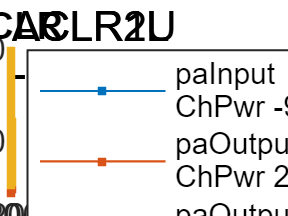

aclrVal_paOutFit = struct with fields:
                       nCC: 1
                      isCA: 0
                       OSR: 2
           ChannelPowerDbm: 24.679
                    ACLRdB: [-53.052 -37.205 -36.959 -52.851]
                      Plot: [1×1 struct]
              CarrierBwMHz: 38
              ChannelBwMHz: 40
         ChannelOffset0MHz: 0
                 AclrBwMHz: 200
                    ScsKHz: 10
             SampleRateMHz: 160
         OverSampleRateMHz: 320
            CarrierFreqMHz: 0
    AdjacentChannelFreqMHz: [-80 -40 40 80]
                      Unit: "MHz"
               Description: "paOutputModelFit"
                     ACLR1: -36.959
                     ACLR2: -52.851


% create fitting signal
if 1
    paOutputModelFit = rfSim_pa_memoryModel({paInput(1:nSamps),coefs_fit},...
        'signalGenerator',Degree_fit_set,MemoryDepth_fit_set,CrossDelay_set,CrossLag_set)...
        * [isNormalizePaSignalFeed*linearGain + ~isNormalizePaSignalFeed];
else
    paInput_tmp = [paInput(1:maxDelay) ;paInput(1:nSamps)];
    paOutputModelFit_tmp = rfSim_pa_memoryModel({paInput_tmp,coefs_fit},...
        'signalGenerator',Degree_fit_set,MemoryDepth_fit_set,CrossDelay_set,CrossLag_set)...
        * [isNormalizePaSignalFeed*linearGain + ~isNormalizePaSignalFeed];
    paOutputModelFit = paOutputModelFit_tmp(1+maxDelay:end);
end

% check the power
deltaPower_modelFit_dB = powerDbm(paOutput(1+maxDelay:end)) - powerDbm(paOutputModelFit(1+maxDelay:end));
if abs(deltaPower_modelFit_dB) > 0.5
    error('delta power is larger than 0.5dB')
end

% Plot
aclrVal_paOutFit = pltComm.ACLR(paOutputModelFit(1+maxDelay:end), {091901, 'paOutputModelFit'}) % plot aclr

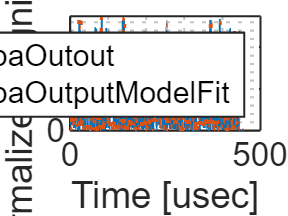

pltComm.TIME(paOutputModelFit(1+0:end), {092001, 'paOutputModelFit'}, [], 'usec'); % plot time

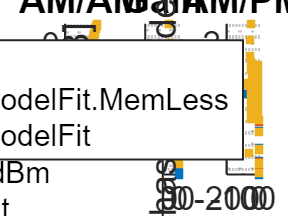

pltComm.AMAM([paInput(1+maxDelay:end), paOutputModelFit(1+maxDelay:end)], {092002, 'paOutputModelFit'}, 0.01, setInputPowerRangeDbm); % plot amam

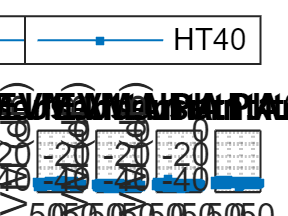

demod_paOutFit = struct with fields:
                isEVMPass: [1 1 1 1]
               isFlatPass: [1 1 1 1]
               isMaskPass: [0 0 0 0]
                   evmRMS: [-30.383 -32.078 -31.24 -29.691]
                 evmPerSc: {[108×1 double]  [108×1 double]  [108×1 double]  [108×1 double]}
            flatDeviation: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}
                  evmSpec: [1×4 table]
                 flatSpec: [1×11 table]
                 maskSpec: [1×7 table]
    outputPowerPerPktsDbm: [24.841 24.886 24.82 24.73]


if 0
    pltComm.AMAM([paInput, paOutput], {092002, 'paOutput'}, 0.01) % plot amam
    figure(092002), subplot(1,3,1), plot(LookupTable.PinDbm, LookupTable.PoutDbm,'DisplayName',dispLegd_LUT, 'LineWidth',2), title('AMAM'), hold on, grid minor, legend
    figure(092002), subplot(1,3,2), plot(LookupTable.PinDbm, LookupTable.GainDb-0*LookupTable.GainDb(1),'DisplayName',dispLegd_LUT, 'LineWidth',2), title('GainCompression'), hold on, grid minor, legend
    figure(092002), subplot(1,3,3), plot(LookupTable.PoutDbm, LookupTable.PhaseShiftDeg,'DisplayName',dispLegd_LUT, 'LineWidth',2), title('AMPM'), hold on, grid minor, legend
end

if 1 % demodulation
    demod_paOutFit = wlanDemodulation(paOutputModelFit, passParams, 'tx')
end

## DPD - comm.DPD (Inverse approach)

deltaPower_dpd_dB =     -0.028615


deltaPower_dpd_dB =     -0.026019


deltaPower_dpd_dB =     -0.023423


deltaPower_dpd_dB =     -0.020828


deltaPower_dpd_dB =     -0.018234


deltaPower_dpd_dB =     -0.015641


deltaPower_dpd_dB =     -0.013048


deltaPower_dpd_dB =     -0.010457


deltaPower_dpd_dB =    -0.0078654


deltaPower_dpd_dB =    -0.0052749


deltaPower_dpd_dB =    -0.0026852


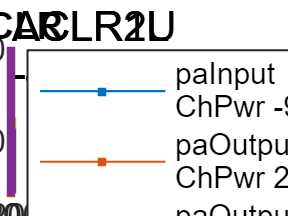

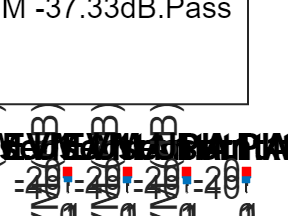

if 0
    dispConditions_dpdFit = "dpdFitMemLess";
else
    dispConditions_dpdFit = "dpdFitMem";
end

if 1
    isGetDpdCoefUseSignal = 'memPolyFit'; % 1: memory polynomail fit, 2: memoryLess polynomila fit, 3: pa output signal
    paOutput_feed4Dpd = paOutputModelFit(1+maxDelay:end);
    paOutput_feed4Dpd = paOutputModelFit;
    paOutput_feed4Dpd_memLess = paOutputModelFit_memLess;
elseif 1*1
    isGetDpdCoefUseSignal = 'memLessPolyFit';
    paOutput_feed4Dpd = paOutput_fitMemLess;
    paOutput_feed4Dpd_memLess = paOutputModelFit_memLess;
else
    isGetDpdCoefUseSignal = 'paOutput'; % 1: memory polynomail fit, 2: memoryLess polynomila fit, 3: pa output signal
    paOutput_feed4Dpd = paOutput_org;
end

if 0 % set signal captured range
    error('!?'), idxCaptured4Dpd = dlSlots;
elseif 1*0
    idxCaptured4Dpd = 1:21976;
else
    idxCaptured4Dpd = 1:nSamps;
end

if 1 % captured pa signal for dpd calculation
    paInput_feed4Dpd = paInput(idxCaptured4Dpd);
    paOutput_feed4Dpd = paOutput_feed4Dpd(idxCaptured4Dpd);
    paOutput_feed4Dpd_memLess = paOutputModelFit_memLess(idxCaptured4Dpd);
end

% remove null samples
if 1
    idxNull = find(paOutput_feed4Dpd(1:maxDelay+1)==0);
    paOutput_feed4Dpd_org = paOutput_feed4Dpd; % store original signal
    paInput_feed4Dpd_org = paInput_feed4Dpd; % store original signal
    paOutput_feed4Dpd(idxNull) = [];
    paInput_feed4Dpd(idxNull) = [];
    dlSlots_feed = dlSlots;
    dlSlots_feed(idxNull) = [];
end

clear dpm % set DPD parameters
dpm.DesiredAmplitudeGaindB = (powerDbm(paOutput_feed4Dpd) - powerDbm(paInput_feed4Dpd))/2 + 0.01*(1); % tuning the linear gain
dpm.PolynomialType = 'Memory polynomial';
dpm.Algorithm = 'Least squares';

if 1
    isMethodCommDPD = "coefficientFinderInverse";
else
    isMethodCommDPD = "comm.DPD";
end

isSweepDPD = 1;
% set memory polynomial parameters for dpd sweep
if 0
Degree_dpm_sweep = [7];
MemoryDepth_dpm_sweep = [0];
else
Degree_dpm_sweep = [5 7];
MemoryDepth_dpm_sweep = [0 1];
end

if 1
    CrossDelay_dpm_set = []; % disable cross delay
    CrossLag_dpm_set = []; % disable cross lag
end

if 1 % initialize
    evm_modelFit = zeros(numel(MemoryDepth_dpm_sweep),numel(Degree_dpm_sweep));
    evmList_dpd = zeros(numel(MemoryDepth_dpm_sweep),numel(Degree_dpm_sweep));
    aclrList_dpd = evmList_dpd;
    deltaPwrList_dpd = evmList_dpd;
end

for K=Degree_dpm_sweep
    for M=MemoryDepth_dpm_sweep

        isDpdModelReused = 0; % set to reuse the dpd model/coeficients
        isCfrAfterDpd = 1; % set turn cfr on/off
        cfr_nIteration = 20; % set cfr_nIteration
        cfr_paprDb_vec = [7.5 8 8.5 9.0 9.5 10 10.5 11 11.5 12 12.5 13]; % set cfr vectors
        cfr_paprDb_vec = [7 8]; % set cfr vectors
        cfr_paprDb_vec = [9 10 11 12 13 14];
        cfr_paprDb_vec = [12]; % set cfr vectors
        for idxCfr=1:numel(cfr_paprDb_vec)

            deltaPower_dpd_dB = 0; % init.
            SIMULATING_tuningPower = 1; % init. tuning the dpm.DesiredAmplitudeGaindB to meeting pa output power w/ dpd
            while SIMULATING_tuningPower
                if isDpdModelReused
                elseif deltaPower_dpd_dB > 0
                    dpm.DesiredAmplitudeGaindB = dpm.DesiredAmplitudeGaindB + 0.005/4;
                elseif deltaPower_dpd_dB < 0
                    dpm.DesiredAmplitudeGaindB = dpm.DesiredAmplitudeGaindB - 0.005/4;
                end

                % set dpd parameters (max.)
                if isSweepDPD
                    % get initial
                    K1 = Degree_dpm_sweep(1);
                    M1 = MemoryDepth_dpm_sweep(1);
                    % set degree and depth from sweeping parameters
                    if 1
                        Degree_dpm_set = {1,1,K};
                        MemoryDepth_dpm_set = {0,1,M};
                    else
                        Degree_dpm_set = {1,2,K};
                        MemoryDepth_dpm_set = {0,1,M};
                    end
                else
                    % set initial
                    K1 = 1;
                    M1 = 0;
                    % set degree and depth from sweeping parameters
                    Degree_dpm_set = Degree_fit_set;
                    MemoryDepth_dpm_set = MemoryDepth_fit_set;
                end

                if 0 % check
                    isequal(Degree_fit_set, Degree_dpm_set)
                    isequal(MemoryDepth_fit_set, MemoryDepth_dpm_set)
                end

                % get maximum delay
                maxDelay_dpd = MemoryDepth_dpm_set{end};

                % update dpm
                dpm.Degree = Degree_dpm_set{end};
                dpm.MemoryDepth = MemoryDepth_dpm_set{end};

                switch isMethodCommDPD % Estimate the dpd memory polynomial coefficients
                    case "comm.DPD"

                        % Generate estimator model
                        estimator = comm.DPDCoefficientEstimator( ...
                            'DesiredAmplitudeGaindB',dpm.DesiredAmplitudeGaindB, ...
                            'PolynomialType',dpm.PolynomialType, ...
                            'Degree',dpm.Degree,'MemoryDepth',(dpm.MemoryDepth+1), ...
                            'Algorithm',dpm.Algorithm); % set 'MemoryDepth' to dpm.MemoryDepth+1 for length alignment
                        
                        if ~isDpdModelReused
                            % Get coefficients
                            switch dispConditions_dpdFit
                                case "dpdFitMemLess"
                                    coefs_dpd = estimator(paInput_feed4Dpd_org,paOutput_feed4Dpd_memLess);
                                case "dpdFitMem"
                                    coefs_dpd = estimator(paInput_feed4Dpd,paOutput_feed4Dpd);
                            end
                            coefs_dpd_org = coefs_dpd; % store original
                        else
                            if deltaPower_dpd_dB == 0
                                coefs_dpd = coefs_dpd_org;
                            elseif deltaPower_dpd_dB > 1
                                coefs_dpd = coefs_dpd * 10^(0.5/20);
                            elseif deltaPower_dpd_dB < -1
                                coefs_dpd = coefs_dpd / 10^(0.5/20);
                            elseif deltaPower_dpd_dB > 0.5
                                coefs_dpd = coefs_dpd * 10^(0.01/20);
                            elseif deltaPower_dpd_dB < -0.5
                                coefs_dpd = coefs_dpd / 10^(0.01/20);
                            elseif deltaPower_dpd_dB > 0.1
                                coefs_dpd = coefs_dpd * 10^(0.05/20);
                            elseif deltaPower_dpd_dB < -0.1
                                coefs_dpd = coefs_dpd / 10^(0.05/20);
                            elseif deltaPower_dpd_dB > 0
                                coefs_dpd = coefs_dpd * 10^(0.002/20);
                            else
                                coefs_dpd = coefs_dpd / 10^(0.002/20);
                            end
                        end

                        % Create dpd model using comm.DPD object
                        dpd_model = comm.DPD('PolynomialType',dpm.PolynomialType,'Coefficients',coefs_dpd);

                        % Generate pa input dpd
                        paInputWiDpd = dpd_model(paInput_feed4Dpd_org);

                        if 0
                            pltComm.AMAM([paInput_feed4Dpd_org(:), paInputWiDpd(:)], {1014, 'paInputWiDpd '+dispConditions_dpdFit}, 0.01); % plot amam
                        end

                        % maxDelay_dpd = 0;

                        coefs_dpd(:);

                    case "coefficientFinderInverse"
                        % Normalize pa output dpd feed
                        LinearGain = 10^(dpm.DesiredAmplitudeGaindB/10);
                        paOutput_cap4Dpd_norm = paOutput_feed4Dpd / LinearGain;

                        % Get the inverse coefs. between pa input/output for dpd used
                        [coefs_paInverse, ~] = rfSim_pa_memoryModel([paInput_feed4Dpd,paOutput_cap4Dpd_norm],...
                            'coefficientFinderInverse',Degree_dpm_set,MemoryDepth_dpm_set,CrossDelay_dpm_set,CrossLag_dpm_set);

                        % Create paInputWiDpd using paInputWiDpd and coefs_paInverse
                        paInputWiDpd = rfSim_pa_memoryModel({paInput_feed4Dpd_org,coefs_paInverse},...
                            'signalGenerator',Degree_dpm_set,MemoryDepth_dpm_set,CrossDelay_dpm_set,CrossLag_dpm_set) * 1;
                        % return coefs.
                        coefs_dpd = coefs_paInverse;
                end

                paInputWiDpdPower_dBm = powerDbm(paInputWiDpd);
                paInput_feed4DpdPower_dbm = powerDbm(paInput_feed4Dpd);
                if 0 % check the dpd expansion of paInput_dpd
                    pltComm.TIME(paInputWiDpd, {092401, 'paInputWiDpd'}, [], 'samples', [], 1); % plot time
                    pltComm.TIME(paInput_feed4Dpd, {092401, 'paInput_feed4Dpd'}, [], 'samples', [], 1); % plot time

                    [ccdfVal_paInWiDpd,~,idxPaprDbMax] = pltComm.CCDF(paInputWiDpd, {[092402], 'paInputWiDpd'}, [], 'max');
                    [ccdfVal_paIn_cap4Dpd,~,idxPaprDbMax] = pltComm.CCDF(paInput_feed4Dpd, {[092402], 'paInput_feed4Dpd'}, [], 'max');
                end

                if isCfrAfterDpd || ~isnan(cfr_paprDb_vec(idxCfr))% apply CFR

                    if 1
                        cfr_paprDb = cfr_paprDb_vec(idxCfr);
                    else
                        cfr_paprDb = 10.0 + 0.5*(-1); % set cfr_paprDb for HT20
                        cfr_paprDb = 10.0 + 5.0*(1); % set cfr_paprDb
                    end

                    paInputWiDpd_org = paInputWiDpd;
                    sprintf('%% set transmit index, remove abnormal points (peak voltage out of dpd expansion point)');
                    % limit the dpd expansion in dB by CFR
                    paInputWiDpdCfr = dfe_cfr_nco_2(paInputWiDpd_org, cfr_paprDb, [], [], cfr_nIteration, []);
                    % reutrn cfr
                    paInputWiDpd = paInputWiDpdCfr;
                    % plot
                    if 0
                        pltComm.TIME(paInputWiDpdCfr, {092401, 'paInputWiDpdCfr'}, [], 'samples', [], 1); % plot time
                        [ccdfVal_paInputWiDpdCfr,~,idxPaprDbOverflow] = pltComm.CCDF(paInputWiDpdCfr, {092402, 'paInputWiDpdCfr'}, [], 14);
                    end
                else
                    cfr_paprDb = nan; % assign nan
                end

                % Apply paInputDPD to pa memoryless model
                switch isGetDpdCoefUseSignal
                    case 'memLessPolyFit'
                        % Degree_dpm_set = {1,1,3};
                        % MemoryDepth_dpm_set = {0,1,0};
                        paOutputWiDpd = paMemLess_obj(paInputWiDpd);
                        idxMem = [1:length(paOutputWiDpd)]';
                    otherwise
                        % Calculate coefficients of pa model
                        if 0
                            [coefs_pa,~,~,evm_modelFit] = rfSim_pa_memoryModel([paInput_feed4Dpd,paOutput_feed4Dpd],...
                                'coefficientFinder',Degree_dpm_set,MemoryDepth_dpm_set,CrossDelay_dpm_set,CrossLag_dpm_set,setInputPowerRangeDbm,Rohm);
                        else
                            [coefs_pa,~,~,evm_modelFit] = rfSim_pa_memoryModel([paInput_feed4PaFit,paOutput_feed4PaFit],...
                                'coefficientFinder',Degree_dpm_set,MemoryDepth_dpm_set,CrossDelay_set,CrossLag_set,setInputPowerRangeDbm,Rohm);
                        end
                        % Create paOutputWiDpd using paInputWiDpd and coefs_pa
                        if 1
                            paOutputWiDpd = rfSim_pa_memoryModel({paInputWiDpd,coefs_pa},...
                                'signalGenerator',Degree_dpm_set,MemoryDepth_dpm_set,CrossDelay_dpm_set,CrossLag_dpm_set) * 1;
                            idxMem = [1+maxDelay_dpd:length(paOutputWiDpd)]'; % remove null signal
                        else
                            paInputWiDpd_tmp = [paInputWiDpd(1:maxDelay_dpd); paInputWiDpd];
                            paOutputWiDpd_tmp = rfSim_pa_memoryModel({paInputWiDpd_tmp,coefs_pa},...
                                'signalGenerator',Degree_dpm_set,MemoryDepth_dpm_set,CrossDelay_dpm_set,CrossLag_dpm_set) * 1;
                            paOutputWiDpd = paOutputWiDpd_tmp(1+maxDelay_dpd:end);
                        end
                end

                if 1 % check delta power
                    paOutput_feed4DpdPower_dbm = powerDbm(paOutput_feed4Dpd(:));
                    paOutputWiDpdPower_dBm = powerDbm(paOutputWiDpd(idxMem));
                    deltaPower_dpd_dB = paOutput_feed4DpdPower_dbm - paOutputWiDpdPower_dBm % check deltaPower_dpd_dB
                    sprintf('delta power between pout and poutWiDpd %.4f dB\n', deltaPower_dpd_dB);
                    deltaPwrList_dpd(M-M1+1,K-K1+1) =deltaPower_dpd_dB;
                    linearGain = 10^((paOutput_feed4DpdPower_dbm - paInput_feed4DpdPower_dbm)/20);
                end

                if abs(deltaPower_dpd_dB) < 0.005
                    SIMULATING_tuningPower = 0;
                end
            end % SIMULATING_tuningPower

            if 1 % check evm
                evmInband_dpd_percent = evm(paInput_feed4Dpd_org(idxMem),paOutputWiDpd(idxMem),'%','inband',...
                    [aclrVal_paIn.SampleRateMHz*1e6, -aclrVal_paIn.CarrierBwMHz*1e6/2, aclrVal_paIn.CarrierBwMHz*1e6/2]); % sampleRate_freqL_freqU
            end

            % Plot
            if 0
                aclrVal_paIn= pltComm.ACLR(paInput_feed4Dpd(:), {091901, 'paInput_feed4Dpd'}); % plot aclr
                aclrVal_paOut = pltComm.ACLR(paOutput_feed4Dpd(:), {091901, 'paOutput_feed4Dpd'}); % plot aclr
            end
            aclrVal_paOutWiDPD = pltComm.ACLR(paOutputWiDpd(idxMem), {091901, 'paOutputWiDpd'}); % plot aclr

            if 0
                isNorm = 0;
                pltComm.TIME(paInput_feed4Dpd(:), {[092711], 'paInput_feed4Dpd'}, [], 'samples', [], isNorm); % plot time
                pltComm.TIME(paOutputWiDpd(idxMem)/linearGain, {[092711], 'paOutputWiDpd/gain'}, [], 'samples', [], isNorm); % plot time
                pltComm.TIME(paOutput_feed4Dpd(:)/linearGain, {[092711], 'paOutput_feed4Dpd/gain'}, [], 'samples', [], isNorm); % plot time
                linearGain = 10^((paOutput_feed4DpdPower_dbm - paInput_feed4DpdPower_dbm)/20);
            end
            if 0
                isNormGain = 1;
                pltComm.AMAM([paInput_feed4Dpd(:), paOutput_feed4Dpd(:)], {09203, 'paOutput_feed4Dpd'}, 0.01,setInputPowerRangeDbm,isNormGain); % plot amam
                pltComm.AMAM([paInput_feed4Dpd_org(:), paInputWiDpd(idxMem)], {09203, 'paInputWiDpd'}, 0.01,setInputPowerRangeDbm,isNormGain); % plot amam
                pltComm.AMAM([paInput_feed4Dpd_org(:), paOutputWiDpd(idxMem)], {09203, 'paOutWiDpd'}, 0.01,setInputPowerRangeDbm,isNormGain); % plot amam
            end
            ccdfVal_paInFed4Dpd = pltComm.CCDF(paInput_feed4Dpd(:), {092003, 'paInput_feed4Dpd'}, 0.01); % plot amam
            pltComm.CCDF(paInputWiDpd(:), {092003, 'paInputWiDpd'}, 0.01); % plot amam
            ccdfVal_paOutFed4Dpd = pltComm.CCDF(paOutput_feed4Dpd(:), {092003, 'paOutput_feed4Dpd'}, 0.01); % plot amam
            ccdfVal_paOutDpd = pltComm.CCDF(paOutputWiDpd(idxMem), {092003, 'paOutputWiDpd'}, 0.01); % plot amam

            % Demodulation
            if 1 % set condtions to dispLgnd
                dispConditions = sprintf(".CFR %.2fdB",cfr_paprDb);
            end
            if 0
                demod_paOut = wlanDemodulation(paOutput_org(:),{passParams,'paOutput_org'},'tx');
                demod_paOut = wlanDemodulation(paOutput_feed4Dpd(:),{passParams,'paOutput_feed4Dpd'},'tx');
            end
            demod_paOutWiDPD = wlanDemodulation(paOutputWiDpd(:),{passParams,['paOutputWiDpd'+dispConditions]},'tx');

            if ~isSweepDPD
                dispLgnd_dpd = sprintf('DPD output,K=%d ,M=%d\nRMSErr. %.2f%%, \x0394Pout %.2fdB', K1, M1, evmInband_dpd_percent, deltaPower_dpd_dB);
            end

            if 1 % print results
                if 1 % conditions
                    result.MCS = MCS_index;
                    result.SignalFormat = signalFormat;
                    result.InputSignalPaprDb = round(ccdfVal_paInFed4Dpd,2);
                    if isDpdModelReused
                        result.DPD = "Coefs_Reused";
                    else
                        result.DPD = "Coefs_New";
                    end
                    result.CfrDb = round(cfr_paprDb,2);
                    result.SampleRateMHz = fsMHz;
                    result.CoefsModel = isGetDpdCoefUseSignal;
                    result.Degree = dpm.Degree;
                    result.Memory = dpm.MemoryDepth;
                    result.DpdMethod = isMethodCommDPD;

                end
                result.PaOutWiDpdChPwrDbm = round(aclrVal_paOutWiDPD.ChannelPowerDbm,2);
                result.PaOutWiDpdEvmRmsDb = round(max(demod_paOutWiDPD.evmRMS),2);
                result.PaOutWiDpdACLR1Db = round(aclrVal_paOutWiDPD.ACLR1,2);
                result.PaOutWiDpdACLR2Db = round(aclrVal_paOutWiDPD.ACLR2,2);
                if 0
                    result.PaOutChPwrDbm = round(aclrVal_paOut.ChannelPowerDbm,2);
                    result.PaOutEvmRmsDb = round(max(demod_paOut.evmRMS),2);
                    result.PaOutACLR1Db = round(aclrVal_paOut.ACLR1,2);
                    result.PaOutACLR2Db = round(aclrVal_paOut.ACLR2,2);
                end
                try
                    result_tab = vertcat(result_tab,struct2table(result));
                catch
                    result_tab = struct2table(result);
                end
            end
        end %idxCfr

    end %M
end %K


if 0 % comparsion dpd coefs. reused
    b = nan(8, 8);
    b(:,1) = [1:8];
    b(:,2) = [7:1:14];
    figure(1008)

    dispLgnd_format = "EHT160 w/"
    color = [0 0.4470 0.7410];

    dispLgnd_format = "HE160 w/"
    color = [0.8500 0.3250 0.0980];

    dispLgnd_format = "VHT80 w/"
    color = [0.9290 0.6940 0.1250];

    dispLgnd_format = "HT40 w/"
    color = [0.4940 0.1840 0.5560];

    dispLgnd_format = "HT20 w/"
    color = [0.4660 0.6740 0.1880];

    plt = plot(b(:,1), b(:,3), 'Color', color, 'LineWidth', 2, 'DisplayName', dispLgnd_format + " DPD coefs. new"); hold on, grid on
    plt = scatter(b(:,1), b(:,3), 'filled', 'CData', color, 'LineWidth', 2, 'DisplayName', dispLgnd_format + " DPD coefs. new"); hold on, grid on
    plt = scatter(b(:,1), b(:,4),  'diamond', 'CData', color, 'LineWidth', 2, 'DisplayName', dispLgnd_format + " DPD coefs. reused from  HT20 27dBm"); hold on, grid on
    plt = scatter(b(:,1), b(:,5), '+', 'CData', color, 'LineWidth', 2, 'DisplayName', dispLgnd_format + " DPD coefs. reused from  HT40 24dBm"); hold on, grid on
    plt = scatter(b(:,1), b(:,6), '*', 'CData', color, 'LineWidth', 2, 'DisplayName', dispLgnd_format + " DPD coefs. reused from  VHT80 23dBm"); hold on, grid on
    plt = scatter(b(:,1), b(:,7), 'square', 'CData', color, 'LineWidth', 2, 'DisplayName', dispLgnd_format + " DPD coefs. reused from  HE160 18dBm"); hold on, grid on
    plt = scatter(b(:,1), b(:,8), 'v', 'CData', color, 'LineWidth', 2, 'DisplayName', dispLgnd_format + " DPD coefs. reused from  EHT160 15dBm"); hold on, grid on
    xticks(b(:,1));
    xtklab = num2cell(b(:,2));
    xticklabels(xtklab), xlabel('CFR [dB]'), ylabel('EVM RMS [dB]'), title(sprintf('PA Output wi/wo Resued DPD Coefficients\n EVM vs CFR'))
    lgd = legend('show', 'Location','eastoutside'),

    lgd.NumColumns = 5

    find_obj_sca = findobj(gca, 'Type', 'scatter')
    find_obj_plt = findobj(gca, 'Type', 'line')

    if 0, delete(find_obj_sca(7:12)), end
    if 0, delete(find_obj_plt(1)), end

end

a = nan(14, 5);
if 0 % summary plot
    a(:,1) = [1:14];
    a(2:13,2) = [7.5:0.5:13];
    figure(1001)
    plt = scatter(a(:,1), a(:,4), 'filled', 'DisplayName', signalFormat); hold on, grid on
    xticks(a(:,1));
    xtklab = num2cell(a(:,2)); xtklab{1} = "DPD off"; if 1, xtklab{end} = "CFR off"; end
    xticklabels(xtklab), xlabel('CFR [dB]'), ylabel('EVM RMS [dB]'), title('PA Output wi/wo DPD EVM vs CFR')
    plt2 = plot(a(:,1), specEVM*ones(size(a,1),1), '--', 'LineWidth', 2, 'Color', get(plt, 'CData'),...
        'DisplayName', sprintf("%s @%.2fdBm Req.",signalFormat, 27.68));
    legend, legend('Location','eastoutside')
end

if 0 % summary plot - aclr
    figure(1004)
    plt3 = scatter(a(:,1), a(:,5), 'filled', 'DisplayName', sprintf("%s %.2fdBm", signalFormat, 27.68)); hold on, grid on
    xticks(a(:,1));
    xticklabels(xtklab), xlabel('CFR [dB]'), ylabel('ACLR [dBc]'), title('PA Output wi/wo DPD ACLR vs CFR')
    legend, lgend('Location','eastoutside')
end


## DPD - Plot Results

if isSweepDPD * 0
    % plot contourf
    plt_contourf(evm_modelFit, [], {Degree_dpm_sweep, MemoryDepth_dpm_sweep},...
        {[091101,1,3,1], 'Polynomial Degree', 'Memory Depth', 'RMS Err. Sweep [%%] for PA output fit signal'}, 'min')

    plt_contourf(evmList_dpd, [], {Degree_dpm_sweep, MemoryDepth_dpm_sweep},...
        {[091101,1,3,2], 'Polynomial Degree', 'Memory Depth', 'EVM Sweep [%%] for PA output w/ DPD signal'}, 'min')

    plt_contourf(deltaPwrList_dpd, [], {Degree_dpm_sweep, MemoryDepth_dpm_sweep},...
        {[091101,1,3,3], 'Polynomial Degree', 'Memory Depth', '\x0394Pout Sweep [dB] for PA output w/ DPD signal'}, 'absMin')
end

function plt_contourf(inputMatrix, contourfLevels, pltTickLabels_cell ,fnum_dispLabels_dispTitle_cell, isMarker)
fnum = fnum_dispLabels_dispTitle_cell{1};
dispXLabel = fnum_dispLabels_dispTitle_cell{2};
dispYLabel = fnum_dispLabels_dispTitle_cell{3};
dispTitle = fnum_dispLabels_dispTitle_cell{4};
setXTicklabel = pltTickLabels_cell{1};
setYTicklabel = pltTickLabels_cell{2};
if isempty(contourfLevels)
    % Set contourfLevels
    minVal = min(inputMatrix,[],'all');
    maxVal = max(inputMatrix,[],'all');
    stepVal = (maxVal - minVal) / 8;
    contourfLevels = minVal:stepVal:maxVal;
end

% plot contourf
figure(fnum(1))
if numel(fnum)==4
    subplot(fnum(2),fnum(3),fnum(4))
end
contourf(inputMatrix, contourfLevels, 'ShowText','on'), grid minor, hold on
c = colorbar;
clim([min(contourfLevels) max(contourfLevels)]);% set colorbar range
c.Ticks = contourfLevels;% set colorbar ticks
xlabel(sprintf(dispXLabel))
ylabel(sprintf(dispYLabel))
title(sprintf(dispTitle))
set(gca, 'XTick', 1:size(inputMatrix,2), 'XTickLabel', setXTicklabel); % xtick
set(gca, 'YTick', 1:size(inputMatrix,1), 'YTickLabel', setYTicklabel); % ytick

if exist('isMarker','var')&&~isempty(isMarker)
    % marker value
    switch isMarker
        case 'max'
            % max
            [inputMatrix_mk, idx] = max(inputMatrix(:)');
        case 'absMax'
            [inputMatrix_mk, idx] = max(abs(inputMatrix(:)'));
        case 'abxMin'
            [inputMatrix_mk, idx] = min(abs(inputMatrix(:)'));
        otherwise
            % min
            [inputMatrix_mk, idx] = min(inputMatrix(:)');
    end
    [xId, yId] = ind2sub(size(inputMatrix), idx);
    scatter(yId, xId, 'red', 'square', 'LineWidth', 2, 'SizeData', 100)
    txt = text(yId+0.1, xId+0.1, [num2str(round(inputMatrix_mk,4)), ' ' ,isMarker]);
    set(txt, 'FontSize', 14, 'Color', 'red', 'FontName', 'Arial', 'FontWeight', 'bold');
end

end
